一些衰减系数的取值

% r:700nm g:550nm b:425nm
%
% kd_0_1 = [0.528 0.0598 0.0222];
% kd_0_1a = [0.536 0.0661 0.0294];
% kd_0_1b = [0.545 0.0726 0.0367];
% kd_0_2 = [0.58 0.0998 0.0672];
% kd_0_3 = [0.616 0.145 0.139];
% kd_0_1c = [0.616 0.145 0.236];
% kd_0_3c = [4.507 0.211 0.416];
% kd_0_5c = [1.02 0.329 0.693];
% kd_0_7c = [0.916 0.462 1.14];
% kd_0_9c = [1.11 0.635 1.9];
% kd_0 = [kd_0_1; kd_0_1a; kd_0_1b; kd_0_2; kd_0_3; kd_0_1c; kd_0_3c; kd_0_5c; kd_0_7c; kd_0_9c];
% 
% kd_1 = [0.595 0.065 0.022];
% kd_1a = [0.595 0.0658 0.0274];
% kd_1b = [0.602 0.0726 0.036];
% kd_2 = [0.624 0.0999 0.0671];
% kd_3 = [0.672 0.144 0.14];
% kd_1c = [0.721 0.129 0.236];
% kd_3c = [4.659 0.187 0.439];
% kd_5c = [1.02 0.255 0.729];
% kd_7c = [0.874 0.409 1.21];
% kd_9c = [0.99 0.696 1.97];
% kd = [kd_1; kd_1a; kd_1b; kd_2; kd_3; kd_1c; kd_3c; kd_5c; kd_7c; kd_9c];

% r:650nm g:550nm b:425nm  +alpha+beta
%
% kd_0_1 = [0.357+0.334, 0.0598+0.062, 0.0222+0.017];
% kd_0_1a = [0.364+0.334, 0.0661+0.0622, 0.0294+0.0225];
% kd_0_1b = [0.371+0.334+0.0450, 0.0726+0.0623+0.0536, 0.0367+0.0246+0.0732];
% kd_0_2 = [0.393+0.334+0.270, 0.0998+0.0622+0.358, 0.0672+0.0257+0.555];
% kd_0_3 = [0.431+0.336+0.737, 0.145+0.0646+0.980, 0.139+0.0449+1.52];
% kd_0_1c = [0.431+0.344+0.274, 0.145+0.076+0.365, 0.236+0.147+0.567];
% kd_0_3c = [0.478+0.346+0.800, 0.211+0.082+1.06, 0.416+0.236+1.65];
% kd_0_5c = [2.43+1.78+2.87, 0.329+0.117+1.33, 0.693+0.437+2.06];
% kd_0_7c = [0.635+0.403+1.77, 0.462+0.195+2.35, 1.14+0.753+3.63];
% kd_0_9c = [0.755+0.456+2.35, 0.635+0.348+3.12, 1.9+1.242+4.84];
% kd_0 = [kd_0_1; kd_0_1a; kd_0_1b; kd_0_2; kd_0_3; kd_0_1c; kd_0_3c; kd_0_5c; kd_0_7c; kd_0_9c] ./ 3;


% r:650nm g:550nm b:425nm
% r:575nm g:525nm b:450nm 近海岸
%
% kd_0_1 = [0.357 0.0598 0.0222];
% kd_0_1a = [0.364 0.0661 0.0294];
% kd_0_1b = [0.371 0.0726 0.0367];
% kd_0_2 = [0.393 0.0998 0.0672];
% kd_0_3 = [0.431 0.145 0.139];
kd_0_1 = [0.163, 0.0398, 0.0182];
kd_0_1a = [0.174, 0.0460, 0.0253];
kd_0_1b = [0.186, 0.0513, 0.0325];
kd_0_2 = [0.223, 0.078, 0.0619];
kd_0_3 = [0.288, 0.122, 0.117];

kd_0_1c = [0.192, 0.122, 0.134];
kd_0_3c = [0.248, 0.198, 0.223];
kd_0_5c = [0.357, 0.315, 0.400];
kd_0_7c = [0.462, 0.494, 0.693];
kd_0_9c = [0.580, 0.777, 1.24];

kd_0 = [kd_0_1; kd_0_1a; kd_0_1b; kd_0_2; kd_0_3; kd_0_1c; kd_0_3c; kd_0_5c; kd_0_7c; kd_0_9c] .* 2.1;

白光的rgb绝对亮度（以G刺激值为1为白光亮度，D50表示白色（x=0.34567, y=0.35850））

rlglbl_white       r  g  b

x_D50 = 0.34567;
y_D50 = 0.35850;
z_D50 = 1 - x_D50 - y_D50;
Y_D50 = 1;
X_D50 = Y_D50 / y_D50 * x_D50;
Z_D50 = Y_D50 / y_D50 - Y_D50 - X_D50;
M_XYZ2RGB = [0.4185 -0.1587 -0.0828; -0.0912 0.2524 0.0157; 0.0009 -0.0025 0.1786] ./ 0.17697

M_XYZ2RGB =     2.3648   -0.8968   -0.4679
   -0.5153    1.4262    0.0887
    0.0051   -0.0141    1.0092


XYZ_D50 = [X_D50; Y_D50; Z_D50]

XYZ_D50 =     0.9642
    1.0000
    0.8252


RGB_D50 = M_XYZ2RGB * XYZ_D50;


x_D65 = 0.31271;
y_D65 = 0.32902;
z_D65 = 1 - x_D65 - y_D65;
Y_D65 = 1;
X_D65 = Y_D65 / y_D65 * x_D65;
Z_D65 = Y_D65 / y_D65 - Y_D65 - X_D65;
M_XYZ2RGB = [0.4185 -0.1587 -0.0828; -0.0912 0.2524 0.0157; 0.0009 -0.0025 0.1786] ./ 0.17697

M_XYZ2RGB =     2.3648   -0.8968   -0.4679
   -0.5153    1.4262    0.0887
    0.0051   -0.0141    1.0092


XYZ_D65 = [X_D65; Y_D65; Z_D65]

XYZ_D65 =     0.9504
    1.0000
    1.0889


RGB_D65 = M_XYZ2RGB * XYZ_D65;


RlGlBl_white = [1; 4.5907; 0.0601];
RlGlBl_D50 = RlGlBl_white .* RGB_D50

RlGlBl_D50 =     0.9973
    4.6024
    0.0495


RlGlBl_D65 = RlGlBl_white .* RGB_D65

RlGlBl_D65 =     0.8413
    4.7424
    0.0655


计算对应的辐射率（幅亮度）

lm2W               r(700)   g(550)   b(430)

r_white

lm2W = [0.004102; 0.994950; 0.011600];
W2lm = [2.802; 679.551; 7.923];

r_white = RlGlBl_D65 ./ W2lm; % RlGlBl_D50 / RlGlBl_D65 可以切换

三色光在1b水体下的衰减系数，距离向量

kd_1b        r(700)     g(550)     b(425)

z

z_max = 20;
z = 1:z_max;

sRGB_color_type = zeros(150, 3);  % 所有水体的最终sRGB颜色的集合，应该是150*3的矩阵

计算不同距离下的衰减比例

reduce_1b =  r  g  b

                  z

%line = 0
for line = 1:10
    % line = line + 1;
    kd_aim = kd_0(line,:)  % 这里的kd随时更换


    beta = z.' * kd_aim
    reduce = exp(-beta)

kd_aim =     0.3423    0.0836    0.0382


beta =     0.3423    0.0836    0.0382
    0.6846    0.1672    0.0764
    1.0269    0.2507    0.1147
    1.3692    0.3343    0.1529
    1.7115    0.4179    0.1911
    2.0538    0.5015    0.2293
    2.3961    0.5851    0.2675
    2.7384    0.6686    0.3058
    3.0807    0.7522    0.3440
    3.4230    0.8358    0.3822


reduce =     0.7101    0.9198    0.9625
    0.5043    0.8461    0.9264
    0.3581    0.7782    0.8917
    0.2543    0.7158    0.8582
    0.1806    0.6584    0.8260
    0.1282    0.6056    0.7951
    0.0911    0.5571    0.7653
    0.0647    0.5124    0.7366
    0.0459    0.4713    0.7089
    0.0326    0.4335    0.6824


kd_aim =     0.3654    0.0966    0.0531


beta =     0.3654    0.0966    0.0531
    0.7308    0.1932    0.1063
    1.0962    0.2898    0.1594
    1.4616    0.3864    0.2125
    1.8270    0.4830    0.2656
    2.1924    0.5796    0.3188
    2.5578    0.6762    0.3719
    2.9232    0.7728    0.4250
    3.2886    0.8694    0.4782
    3.6540    0.9660    0.5313


reduce =     0.6939    0.9079    0.9483
    0.4815    0.8243    0.8992
    0.3341    0.7484    0.8527
    0.2319    0.6795    0.8085
    0.1609    0.6169    0.7667
    0.1116    0.5601    0.7270
    0.0775    0.5085    0.6894
    0.0538    0.4617    0.6537
    0.0373    0.4192    0.6199
    0.0259    0.3806    0.5878


kd_aim =     0.3906    0.1077    0.0683


beta =     0.3906    0.1077    0.0683
    0.7812    0.2155    0.1365
    1.1718    0.3232    0.2048
    1.5624    0.4309    0.2730
    1.9530    0.5387    0.3413
    2.3436    0.6464    0.4095
    2.7342    0.7541    0.4778
    3.1248    0.8618    0.5460
    3.5154    0.9696    0.6143
    3.9060    1.0773    0.6825


reduce =     0.6767    0.8979    0.9340
    0.4579    0.8062    0.8724
    0.3098    0.7238    0.8149
    0.2096    0.6499    0.7611
    0.1418    0.5835    0.7109
    0.0960    0.5239    0.6640
    0.0649    0.4704    0.6202
    0.0439    0.4224    0.5793
    0.0297    0.3792    0.5410
    0.0201    0.3405    0.5054


kd_aim =     0.4683    0.1638    0.1300


beta =     0.4683    0.1638    0.1300
    0.9366    0.3276    0.2600
    1.4049    0.4914    0.3900
    1.8732    0.6552    0.5200
    2.3415    0.8190    0.6500
    2.8098    0.9828    0.7799
    3.2781    1.1466    0.9099
    3.7464    1.3104    1.0399
    4.2147    1.4742    1.1699
    4.6830    1.6380    1.2999


reduce =     0.6261    0.8489    0.8781
    0.3920    0.7207    0.7711
    0.2454    0.6118    0.6771
    0.1536    0.5193    0.5945
    0.0962    0.4409    0.5221
    0.0602    0.3743    0.4584
    0.0377    0.3177    0.4026
    0.0236    0.2697    0.3535
    0.0148    0.2290    0.3104
    0.0093    0.1944    0.2726


kd_aim =     0.6048    0.2562    0.2457


beta =     0.6048    0.2562    0.2457
    1.2096    0.5124    0.4914
    1.8144    0.7686    0.7371
    2.4192    1.0248    0.9828
    3.0240    1.2810    1.2285
    3.6288    1.5372    1.4742
    4.2336    1.7934    1.7199
    4.8384    2.0496    1.9656
    5.4432    2.3058    2.2113
    6.0480    2.5620    2.4570


reduce =     0.5462    0.7740    0.7822
    0.2983    0.5991    0.6118
    0.1629    0.4637    0.4785
    0.0890    0.3589    0.3743
    0.0486    0.2778    0.2927
    0.0265    0.2150    0.2290
    0.0145    0.1664    0.1791
    0.0079    0.1288    0.1401
    0.0043    0.0997    0.1096
    0.0024    0.0772    0.0857


kd_aim = 1×3
    0.4032    0.2562    0.2814


beta = 10×3
    0.4032    0.2562    0.2814
    0.8064    0.5124    0.5628
    1.2096    0.7686    0.8442
    1.6128    1.0248    1.1256
    2.0160    1.2810    1.4070
    2.4192    1.5372    1.6884
    2.8224    1.7934    1.9698
    3.2256    2.0496    2.2512
    3.6288    2.3058    2.5326
    4.0320    2.5620    2.8140


reduce = 10×3
    0.6682    0.7740    0.7547
    0.4465    0.5991    0.5696
    0.2983    0.4637    0.4299
    0.1993    0.3589    0.3245
    0.1332    0.2778    0.2449
    0.0890    0.2150    0.1848
    0.0595    0.1664    0.1395
    0.0397    0.1288    0.1053
    0.0265    0.0997    0.0795
    0.0177    0.0772    0.0600


kd_aim = 1×3
    0.5208    0.4158    0.4683


beta = 10×3
    0.5208    0.4158    0.4683
    1.0416    0.8316    0.9366
    1.5624    1.2474    1.4049
    2.0832    1.6632    1.8732
    2.6040    2.0790    2.3415
    3.1248    2.4948    2.8098
    3.6456    2.9106    3.2781
    4.1664    3.3264    3.7464
    4.6872    3.7422    4.2147
    5.2080    4.1580    4.6830


reduce = 10×3
    0.5940    0.6598    0.6261
    0.3529    0.4354    0.3920
    0.2096    0.2873    0.2454
    0.1245    0.1895    0.1536
    0.0740    0.1251    0.0962
    0.0439    0.0825    0.0602
    0.0261    0.0544    0.0377
    0.0155    0.0359    0.0236
    0.0092    0.0237    0.0148
    0.0055    0.0156    0.0093


kd_aim = 1×3
    0.7497    0.6615    0.8400


beta = 10×3
    0.7497    0.6615    0.8400
    1.4994    1.3230    1.6800
    2.2491    1.9845    2.5200
    2.9988    2.6460    3.3600
    3.7485    3.3075    4.2000
    4.4982    3.9690    5.0400
    5.2479    4.6305    5.8800
    5.9976    5.2920    6.7200
    6.7473    5.9535    7.5600
    7.4970    6.6150    8.4000


reduce = 10×3
    0.4725    0.5161    0.4317
    0.2233    0.2663    0.1864
    0.1055    0.1374    0.0805
    0.0498    0.0709    0.0347
    0.0236    0.0366    0.0150
    0.0111    0.0189    0.0065
    0.0053    0.0097    0.0028
    0.0025    0.0050    0.0012
    0.0012    0.0026    0.0005
    0.0006    0.0013    0.0002


kd_aim = 1×3
    0.9702    1.0374    1.4553


beta = 10×3
    0.9702    1.0374    1.4553
    1.9404    2.0748    2.9106
    2.9106    3.1122    4.3659
    3.8808    4.1496    5.8212
    4.8510    5.1870    7.2765
    5.8212    6.2244    8.7318
    6.7914    7.2618   10.1871
    7.7616    8.2992   11.6424
    8.7318    9.3366   13.0977
    9.7020   10.3740   14.5530


reduce = 10×3
    0.3790    0.3544    0.2333
    0.1436    0.1256    0.0544
    0.0544    0.0445    0.0127
    0.0206    0.0158    0.0030
    0.0078    0.0056    0.0007
    0.0030    0.0020    0.0002
    0.0011    0.0007    0.0000
    0.0004    0.0002    0.0000
    0.0002    0.0001    0.0000
    0.0001    0.0000    0.0000


kd_aim = 1×3
    1.2180    1.6317    2.6040


beta = 10×3
    1.2180    1.6317    2.6040
    2.4360    3.2634    5.2080
    3.6540    4.8951    7.8120
    4.8720    6.5268   10.4160
    6.0900    8.1585   13.0200
    7.3080    9.7902   15.6240
    8.5260   11.4219   18.2280
    9.7440   13.0536   20.8320
   10.9620   14.6853   23.4360
   12.1800   16.3170   26.0400


reduce = 10×3
    0.2958    0.1956    0.0740
    0.0875    0.0383    0.0055
    0.0259    0.0075    0.0004
    0.0077    0.0015    0.0000
    0.0023    0.0003    0.0000
    0.0007    0.0001    0.0000
    0.0002    0.0000    0.0000
    0.0001    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


计算rgb衰减之后的幅亮度

r_withZ

    r_white_rep = repmat(r_white', z_max, 1);
    r_withZ = r_white_rep .* reduce;

幅亮度转化为亮度 

Wtolm, rlglbl_withZ

    W2lm_rep = repmat(W2lm', z_max, 1);
    rlglbl_withZ = r_withZ .* W2lm_rep

rlglbl_withZ =     0.5975    4.3621    0.0630
    0.4243    4.0123    0.0607
    0.3013    3.6906    0.0584
    0.2140    3.3947    0.0562
    0.1519    3.1225    0.0541
    0.1079    2.8721    0.0521
    0.0766    2.6418    0.0501
    0.0544    2.4300    0.0482
    0.0386    2.2352    0.0464
    0.0274    2.0559    0.0447


rlglbl_withZ =     0.5838    4.3057    0.0621
    0.4051    3.9092    0.0589
    0.2811    3.5492    0.0558
    0.1951    3.2224    0.0529
    0.1354    2.9257    0.0502
    0.0939    2.6563    0.0476
    0.0652    2.4117    0.0451
    0.0452    2.1896    0.0428
    0.0314    1.9880    0.0406
    0.0218    1.8050    0.0385


rlglbl_withZ =     0.5693    4.2580    0.0612
    0.3852    3.8232    0.0571
    0.2607    3.4327    0.0534
    0.1764    3.0821    0.0498
    0.1193    2.7673    0.0466
    0.0808    2.4847    0.0435
    0.0546    2.2309    0.0406
    0.0370    2.0031    0.0379
    0.0250    1.7985    0.0354
    0.0169    1.6148    0.0331


rlglbl_withZ =     0.5267    4.0258    0.0575
    0.3298    3.4176    0.0505
    0.2065    2.9012    0.0443
    0.1293    2.4629    0.0389
    0.0809    2.0908    0.0342
    0.0507    1.7749    0.0300
    0.0317    1.5067    0.0264
    0.0199    1.2791    0.0231
    0.0124    1.0858    0.0203
    0.0078    0.9218    0.0178


rlglbl_withZ =     0.4595    3.6705    0.0512
    0.2510    2.8409    0.0401
    0.1371    2.1989    0.0313
    0.0749    1.7019    0.0245
    0.0409    1.3172    0.0192
    0.0223    1.0195    0.0150
    0.0122    0.7891    0.0117
    0.0067    0.6108    0.0092
    0.0036    0.4727    0.0072
    0.0020    0.3659    0.0056


rlglbl_withZ = 10×3
    0.5622    3.6705    0.0494
    0.3756    2.8409    0.0373
    0.2510    2.1989    0.0282
    0.1677    1.7019    0.0212
    0.1121    1.3172    0.0160
    0.0749    1.0195    0.0121
    0.0500    0.7891    0.0091
    0.0334    0.6108    0.0069
    0.0223    0.4727    0.0052
    0.0149    0.3659    0.0039


rlglbl_withZ = 10×3
    0.4998    3.1291    0.0410
    0.2969    2.0646    0.0257
    0.1764    1.3622    0.0161
    0.1048    0.8988    0.0101
    0.0622    0.5931    0.0063
    0.0370    0.3913    0.0039
    0.0220    0.2582    0.0025
    0.0130    0.1704    0.0015
    0.0078    0.1124    0.0010
    0.0046    0.0742    0.0006


rlglbl_withZ = 10×3
    0.3975    2.4474    0.0283
    0.1878    1.2631    0.0122
    0.0888    0.6518    0.0053
    0.0419    0.3364    0.0023
    0.0198    0.1736    0.0010
    0.0094    0.0896    0.0004
    0.0044    0.0462    0.0002
    0.0021    0.0239    0.0001
    0.0010    0.0123    0.0000
    0.0005    0.0064    0.0000


rlglbl_withZ = 10×3
    0.3189    1.6806    0.0153
    0.1209    0.5956    0.0036
    0.0458    0.2110    0.0008
    0.0174    0.0748    0.0002
    0.0066    0.0265    0.0000
    0.0025    0.0094    0.0000
    0.0009    0.0033    0.0000
    0.0004    0.0012    0.0000
    0.0001    0.0004    0.0000
    0.0001    0.0001    0.0000


rlglbl_withZ = 10×3
    0.2489    0.9276    0.0048
    0.0736    0.1814    0.0004
    0.0218    0.0355    0.0000
    0.0064    0.0069    0.0000
    0.0019    0.0014    0.0000
    0.0006    0.0003    0.0000
    0.0002    0.0001    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


亮度转化为标准亮度CIE RGB（G=1时为白色亮度）

RGB_withZ

    RlGlBl_normalize_rep = repmat(RlGlBl_white', z_max, 1);
    RGB_withZ = rlglbl_withZ ./ RlGlBl_normalize_rep

RGB_withZ =     0.5975    0.9502    1.0488
    0.4243    0.8740    1.0094
    0.3013    0.8039    0.9716
    0.2140    0.7395    0.9352
    0.1519    0.6802    0.9001
    0.1079    0.6256    0.8663
    0.0766    0.5755    0.8339
    0.0544    0.5293    0.8026
    0.0386    0.4869    0.7725
    0.0274    0.4479    0.7435


RGB_withZ =     0.5838    0.9379    1.0333
    0.4051    0.8516    0.9798
    0.2811    0.7731    0.9291
    0.1951    0.7019    0.8810
    0.1354    0.6373    0.8354
    0.0939    0.5786    0.7922
    0.0652    0.5253    0.7512
    0.0452    0.4770    0.7123
    0.0314    0.4331    0.6755
    0.0218    0.3932    0.6405


RGB_withZ =     0.5693    0.9275    1.0177
    0.3852    0.8328    0.9506
    0.2607    0.7478    0.8879
    0.1764    0.6714    0.8293
    0.1193    0.6028    0.7746
    0.0808    0.5412    0.7235
    0.0546    0.4860    0.6758
    0.0370    0.4363    0.6312
    0.0250    0.3918    0.5895
    0.0169    0.3518    0.5507


RGB_withZ =     0.5267    0.8770    0.9568
    0.3298    0.7445    0.8402
    0.2065    0.6320    0.7378
    0.1293    0.5365    0.6478
    0.0809    0.4554    0.5689
    0.0507    0.3866    0.4995
    0.0317    0.3282    0.4386
    0.0199    0.2786    0.3852
    0.0124    0.2365    0.3382
    0.0078    0.2008    0.2970


RGB_withZ =     0.4595    0.7996    0.8523
    0.2510    0.6188    0.6666
    0.1371    0.4790    0.5214
    0.0749    0.3707    0.4078
    0.0409    0.2869    0.3190
    0.0223    0.2221    0.2495
    0.0122    0.1719    0.1951
    0.0067    0.1330    0.1526
    0.0036    0.1030    0.1194
    0.0020    0.0797    0.0934


RGB_withZ = 10×3
    0.5622    0.7996    0.8224
    0.3756    0.6188    0.6207
    0.2510    0.4790    0.4684
    0.1677    0.3707    0.3535
    0.1121    0.2869    0.2668
    0.0749    0.2221    0.2014
    0.0500    0.1719    0.1520
    0.0334    0.1330    0.1147
    0.0223    0.1030    0.0866
    0.0149    0.0797    0.0653


RGB_withZ = 10×3
    0.4998    0.6816    0.6822
    0.2969    0.4497    0.4271
    0.1764    0.2967    0.2674
    0.1048    0.1958    0.1674
    0.0622    0.1292    0.1048
    0.0370    0.0852    0.0656
    0.0220    0.0562    0.0411
    0.0130    0.0371    0.0257
    0.0078    0.0245    0.0161
    0.0046    0.0162    0.0101


RGB_withZ = 10×3
    0.3975    0.5331    0.4704
    0.1878    0.2751    0.2031
    0.0888    0.1420    0.0877
    0.0419    0.0733    0.0378
    0.0198    0.0378    0.0163
    0.0094    0.0195    0.0071
    0.0044    0.0101    0.0030
    0.0021    0.0052    0.0013
    0.0010    0.0027    0.0006
    0.0005    0.0014    0.0002


RGB_withZ = 10×3
    0.3189    0.3661    0.2542
    0.1209    0.1297    0.0593
    0.0458    0.0460    0.0138
    0.0174    0.0163    0.0032
    0.0066    0.0058    0.0008
    0.0025    0.0020    0.0002
    0.0009    0.0007    0.0000
    0.0004    0.0003    0.0000
    0.0001    0.0001    0.0000
    0.0001    0.0000    0.0000


RGB_withZ = 10×3
    0.2489    0.2021    0.0806
    0.0736    0.0395    0.0060
    0.0218    0.0077    0.0004
    0.0064    0.0015    0.0000
    0.0019    0.0003    0.0000
    0.0006    0.0001    0.0000
    0.0002    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


获得CIE XYZ的值

XYZ_withZ

XYZ_normalize_withZ 

两个变量差了一个0.17697的控制因子，都是3*15的矩阵

    M_RGB2XYZ = [2.768 1.751 1.130; 1 4.590 0.060; 0 0.056 5.594];
    M_normalize_RGB2XYZ = [0.49 0.31 0.2; 0.17697 0.81240 0.01063; 0 0.01 0.99];

    XYZ_withZ = M_RGB2XYZ * RGB_withZ';
    XYZ_normalize_withZ = M_normalize_RGB2XYZ * RGB_withZ'

XYZ_normalize_withZ =     0.7971    0.6807    0.5912    0.5211    0.4653    0.4201    0.3827    0.3513    0.3244    0.3010    0.2804    0.2620    0.2455    0.2304    0.2167    0.2040    0.1924    0.1815    0.1715    0.1621
    0.8888    0.7959    0.7168    0.6486    0.5890    0.5366    0.4899    0.4482    0.4106    0.3766    0.3457    0.3176    0.2919    0.2685    0.2470    0.2273    0.2092    0.1926    0.1773    0.1633
    1.0478    1.0081    0.9699    0.9332    0.8979    0.8639    0.8313    0.7999    0.7696    0.7406    0.7126    0.6857    0.6598    0.6349    0.6110    0.5880    0.5658    0.5445    0.5240    0.5042


XYZ_normalize_withZ =     0.7835    0.6585    0.5632    0.4894    0.4310    0.3838    0.3450    0.3125    0.2847    0.2607    0.2395    0.2208    0.2040    0.1889    0.1751    0.1626    0.1511    0.1406    0.1309    0.1220
    0.8763    0.7739    0.6877    0.6142    0.5506    0.4951    0.4463    0.4031    0.3645    0.3301    0.2991    0.2713    0.2461    0.2234    0.2029    0.1843    0.1674    0.1521    0.1383    0.1257
    1.0323    0.9785    0.9275    0.8792    0.8335    0.7901    0.7490    0.7100    0.6731    0.6381    0.6049    0.5734    0.5436    0.5154    0.4886    0.4632    0.4392    0.4164    0.3948    0.3743


XYZ_normalize_withZ =     0.7700    0.6370    0.5371    0.4604    0.4003    0.3521    0.3126    0.2796    0.2516    0.2275    0.2064    0.1878    0.1712    0.1564    0.1431    0.1311    0.1201    0.1102    0.1012    0.0930
    0.8651    0.7548    0.6630    0.5855    0.5191    0.4617    0.4117    0.3677    0.3290    0.2946    0.2641    0.2369    0.2126    0.1908    0.1713    0.1539    0.1383    0.1242    0.1116    0.1003
    1.0168    0.9494    0.8865    0.8277    0.7729    0.7217    0.6739    0.6292    0.5876    0.5487    0.5123    0.4784    0.4468    0.4172    0.3896    0.3638    0.3397    0.3173    0.2963    0.2767


XYZ_normalize_withZ =     0.7213    0.5604    0.4446    0.3592    0.2946    0.2446    0.2050    0.1731    0.1471    0.1255    0.1074    0.0922    0.0792    0.0682    0.0588    0.0508    0.0438    0.0379    0.0327    0.0283
    0.8158    0.6721    0.5578    0.4656    0.3904    0.3284    0.2769    0.2340    0.1979    0.1677    0.1421    0.1205    0.1023    0.0868    0.0737    0.0626    0.0531    0.0451    0.0383    0.0326
    0.9560    0.8392    0.7367    0.6467    0.5677    0.4984    0.4375    0.3841    0.3372    0.2960    0.2599    0.2282    0.2003    0.1759    0.1544    0.1355    0.1190    0.1045    0.0917    0.0805


XYZ_normalize_withZ =     0.6435    0.4481    0.3199    0.2332    0.1728    0.1297    0.0983    0.0750    0.0576    0.0444    0.0343    0.0265    0.0206    0.0159    0.0124    0.0096    0.0075    0.0058    0.0045    0.0035
    0.7399    0.5543    0.4189    0.3188    0.2437    0.1870    0.1439    0.1109    0.0856    0.0661    0.0511    0.0395    0.0306    0.0236    0.0183    0.0142    0.0110    0.0085    0.0066    0.0051
    0.8517    0.6661    0.5210    0.4074    0.3187    0.2492    0.1949    0.1524    0.1192    0.0932    0.0729    0.0570    0.0446    0.0349    0.0273    0.0213    0.0167    0.0131    0.0102    0.0080


XYZ_normalize_withZ = 3×20
    0.6878    0.5000    0.3652    0.2678    0.1972    0.1458    0.1082    0.0806    0.0602    0.0451    0.0339    0.0255    0.0193    0.0146    0.0110    0.0084    0.0064    0.0048    0.0037    0.0028
    0.7578    0.5758    0.4385    0.3346    0.2558    0.1958    0.1501    0.1152    0.0885    0.0681    0.0524    0.0404    0.0311    0.0240    0.0185    0.0143    0.0110    0.0085    0.0066    0.0051
    0.8221    0.6207    0.4685    0.3537    0.2670    0.2016    0.1522    0.1149    0.0867    0.0655    0.0494    0.0373    0.0282    0.0213    0.0161    0.0121    0.0092    0.0069    0.0052    0.0039


XYZ_normalize_withZ = 3×20
    0.5926    0.3703    0.2319    0.1455    0.0915    0.0577    0.0364    0.0230    0.0146    0.0093    0.0059    0.0038    0.0024    0.0015    0.0010    0.0006    0.0004    0.0003    0.0002    0.0001
    0.6494    0.4224    0.2751    0.1794    0.1171    0.0765    0.0500    0.0327    0.0214    0.0140    0.0092    0.0060    0.0040    0.0026    0.0017    0.0011    0.0007    0.0005    0.0003    0.0002
    0.6822    0.4273    0.2677    0.1677    0.1050    0.0658    0.0412    0.0258    0.0162    0.0101    0.0064    0.0040    0.0025    0.0016    0.0010    0.0006    0.0004    0.0002    0.0002    0.0001


XYZ_normalize_withZ = 3×20
    0.4541    0.2180    0.1050    0.0508    0.0247    0.0120    0.0059    0.0029    0.0014    0.0007    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5085    0.2589    0.1320    0.0674    0.0344    0.0176    0.0090    0.0046    0.0024    0.0012    0.0006    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4710    0.2038    0.0882    0.0382    0.0166    0.0072    0.0031    0.0014    0.0006    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


XYZ_normalize_withZ = 3×20
    0.3206    0.1113    0.0395    0.0142    0.0052    0.0019    0.0007    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3565    0.1274    0.0456    0.0163    0.0059    0.0021    0.0008    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2554    0.0600    0.0142    0.0034    0.0008    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


XYZ_normalize_withZ = 3×20
    0.2007    0.0495    0.0132    0.0036    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2091    0.0452    0.0101    0.0024    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0818    0.0063    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


CIE XYZ 转化为 sRGB'（未校准空间）

sRGB_normalize_withZ

    M_XYZ2sRGBn = [3.2404542, -1.5371385, -0.4985314; -0.9692660, 1.8760108, 0.0415560; 0.0556434, -0.2040259, 1.0572252];
    sRGB_normalize_withZ = M_XYZ2sRGBn * XYZ_normalize_withZ;

优化sRGB'空间内的数据

- 负数归0

- 伽马矫正

    sRGB_moreThan0_withZ = sRGB_normalize_withZ .* (sRGB_normalize_withZ > 0)

sRGB_moreThan0_withZ =     0.6943    0.4800    0.3304    0.2265    0.1548    0.1058    0.0726    0.0506    0.0363    0.0273    0.0219    0.0190    0.0177    0.0175    0.0179    0.0187    0.0197    0.0208    0.0219    0.0229
    0.9384    0.8751    0.8120    0.7504    0.6913    0.6353    0.5827    0.5336    0.4879    0.4455    0.4064    0.3704    0.3372    0.3067    0.2787    0.2530    0.2295    0.2079    0.1882    0.1702
    0.9708    0.9413    0.9121    0.8833    0.8550    0.8273    0.8002    0.7737    0.7480    0.7229    0.6984    0.6747    0.6517    0.6293    0.6076    0.5866    0.5662    0.5464    0.5273    0.5088


sRGB_moreThan0_withZ =     0.6773    0.4563    0.3056    0.2035    0.1348    0.0889    0.0587    0.0391    0.0267    0.0192    0.0149    0.0126    0.0117    0.0116    0.0120    0.0127    0.0134    0.0142    0.0149    0.0155
    0.9274    0.8543    0.7828    0.7143    0.6498    0.5896    0.5340    0.4828    0.4359    0.3931    0.3541    0.3187    0.2866    0.2575    0.2312    0.2074    0.1859    0.1664    0.1489    0.1331
    0.9562    0.9132    0.8716    0.8315    0.7928    0.7556    0.7200    0.6858    0.6530    0.6217    0.5918    0.5632    0.5359    0.5098    0.4849    0.4612    0.4386    0.4170    0.3964    0.3768


sRGB_moreThan0_withZ =     0.6586    0.4307    0.2793    0.1794    0.1139    0.0714    0.0442    0.0271    0.0168    0.0107    0.0074    0.0059    0.0055    0.0056    0.0061    0.0067    0.0074    0.0080    0.0086    0.0091
    0.9188    0.8381    0.7601    0.6865    0.6179    0.5549    0.4973    0.4450    0.3977    0.3550    0.3167    0.2822    0.2513    0.2237    0.1989    0.1768    0.1571    0.1394    0.1237    0.1096
    0.9414    0.8852    0.8318    0.7813    0.7335    0.6884    0.6458    0.6058    0.5681    0.5326    0.4993    0.4679    0.4385    0.4108    0.3849    0.3605    0.3377    0.3162    0.2961    0.2772


sRGB_moreThan0_withZ =     0.6068    0.3645    0.2161    0.1259    0.0716    0.0393    0.0206    0.0099    0.0042    0.0012         0         0         0         0    0.0004    0.0007    0.0010    0.0013    0.0014    0.0016
    0.8711    0.7525    0.6461    0.5522    0.4704    0.3997    0.3390    0.2871    0.2428    0.2052    0.1733    0.1463    0.1234    0.1040    0.0877    0.0738    0.0622    0.0523    0.0440    0.0370
    0.8844    0.7813    0.6898    0.6087    0.5370    0.4735    0.4175    0.3680    0.3243    0.2857    0.2517    0.2217    0.1953    0.1720    0.1515    0.1334    0.1174    0.1033    0.0910    0.0801


sRGB_moreThan0_withZ =     0.5232    0.2682    0.1331    0.0625    0.0264    0.0085    0.0002         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.7998    0.6331    0.4975    0.3889    0.3030    0.2355    0.1827    0.1416    0.1097    0.0849    0.0657    0.0508    0.0393    0.0303    0.0235    0.0181    0.0140    0.0108    0.0084    0.0065
    0.7853    0.6161    0.4831    0.3787    0.2968    0.2325    0.1822    0.1427    0.1118    0.0876    0.0686    0.0537    0.0421    0.0329    0.0258    0.0202    0.0158    0.0124    0.0097    0.0076


sRGB_moreThan0_withZ = 3×20
    0.6541    0.4258    0.2756    0.1771    0.1128    0.0710    0.0440    0.0267    0.0157    0.0088    0.0046    0.0020    0.0005         0         0         0         0         0         0         0
    0.7891    0.6214    0.4882    0.3829    0.2998    0.2344    0.1831    0.1428    0.1114    0.0867    0.0675    0.0525    0.0409    0.0318    0.0247    0.0192    0.0149    0.0116    0.0090    0.0070
    0.7529    0.5665    0.4262    0.3206    0.2411    0.1813    0.1363    0.1024    0.0770    0.0578    0.0435    0.0326    0.0245    0.0184    0.0138    0.0104    0.0078    0.0058    0.0044    0.0033


sRGB_moreThan0_withZ = 3×20
    0.5820    0.3376    0.1951    0.1122    0.0642    0.0365    0.0206    0.0115    0.0063    0.0034    0.0018    0.0009    0.0005    0.0002    0.0001    0.0000         0         0         0         0
    0.6723    0.4513    0.3025    0.2025    0.1353    0.0903    0.0602    0.0401    0.0267    0.0178    0.0118    0.0079    0.0052    0.0035    0.0023    0.0015    0.0010    0.0007    0.0004    0.0003
    0.6217    0.3862    0.2398    0.1488    0.0923    0.0572    0.0354    0.0219    0.0136    0.0084    0.0052    0.0032    0.0020    0.0012    0.0007    0.0005    0.0003    0.0002    0.0001    0.0001


sRGB_moreThan0_withZ = 3×20
    0.4552    0.2067    0.0935    0.0422    0.0189    0.0084    0.0037    0.0016    0.0007    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0
    0.5333    0.2830    0.1495    0.0787    0.0413    0.0216    0.0113    0.0059    0.0031    0.0016    0.0008    0.0004    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4195    0.1748    0.0722    0.0295    0.0119    0.0047    0.0018    0.0007    0.0002    0.0001    0.0000         0         0         0         0         0         0         0         0         0


sRGB_moreThan0_withZ = 3×20
    0.3635    0.1349    0.0507    0.0192    0.0073    0.0028    0.0011    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3688    0.1336    0.0479    0.0170    0.0060    0.0021    0.0007    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2151    0.0437    0.0079    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sRGB_moreThan0_withZ = 3×20
    0.2883    0.0879    0.0268    0.0081    0.0024    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2010    0.0371    0.0063    0.0009    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0550    0.0002         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


    
    sRGB_withZ = sRGB_moreThan0_withZ;
    [r,c] = size(sRGB_moreThan0_withZ)

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

r = 3

c = 20

    for i = 1:r        % 建立for循环嵌套
        for k = 1:c
            if sRGB_moreThan0_withZ(i,k) > 1 % 一般来说不可能（但是出现了）
                sRGB_withZ(i,k) = 1;
            elseif sRGB_moreThan0_withZ(i,k) <= 0.0031308     % 读取矩阵每个位置数据，先行后列
                sRGB_withZ(i,k) = 12.92 * sRGB_moreThan0_withZ(i,k);
            else
                sRGB_withZ(i,k) = 1.055 * power(sRGB_moreThan0_withZ(i,k), 1 / 2.4) - 0.055;
            end
        end
    end
    
    % sRGB_255_withZ = round(sRGB_withZ .* 255)'
    sRGB_255_withZ = sRGB_withZ'

sRGB_255_withZ =     0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_255_withZ =     0.8419    0.9674    0.9805
    0.7058    0.9330    0.9609
    0.5888    0.8977    0.9413
    0.4885    0.8620    0.9219
    0.4027    0.8265    0.9027
    0.3298    0.7916    0.8837
    0.2687    0.7573    0.8650
    0.2183    0.7239    0.8466
    0.1783    0.6914    0.8284
    0.1482    0.6600    0.8105


sRGB_255_withZ =     0.8315    0.9634    0.9738
    0.6877    0.9251    0.9477
    0.5651    0.8861    0.9221
    0.4606    0.8469    0.8969
    0.3716    0.8083    0.8722
    0.2962    0.7704    0.8480
    0.2326    0.7336    0.8243
    0.1797    0.6979    0.8011
    0.1370    0.6634    0.7785
    0.1044    0.6303    0.7564


sRGB_255_withZ =     0.8017    0.9410    0.9474
    0.6378    0.8821    0.8969
    0.5022    0.8244    0.8488
    0.3899    0.7687    0.8029
    0.2967    0.7155    0.7592
    0.2190    0.6649    0.7176
    0.1541    0.6172    0.6781
    0.0994    0.5722    0.6406
    0.0524    0.5300    0.6049
    0.0161    0.4904    0.5710


sRGB_255_withZ =     0.7504    0.9062    0.8989
    0.5546    0.8170    0.8072
    0.4003    0.7337    0.7241
    0.2773    0.6568    0.6489
    0.1770    0.5865    0.5810
    0.0899    0.5226    0.5195
    0.0024    0.4646    0.4639
         0    0.4123    0.4137
         0    0.3650    0.3684
         0    0.3225    0.3274


sRGB_255_withZ = 10×3
    0.8290    0.9009    0.8823
    0.6842    0.8103    0.7776
    0.5617    0.7275    0.6845
    0.4579    0.6522    0.6017
    0.3700    0.5836    0.5282
    0.2954    0.5214    0.4629
    0.2321    0.4650    0.4048
    0.1781    0.4139    0.3533
    0.1318    0.3677    0.3075
    0.0919    0.3259    0.2668


sRGB_255_withZ = 10×3
    0.7870    0.8391    0.8104
    0.6161    0.7023    0.6547
    0.4790    0.5860    0.5269
    0.3691    0.4873    0.4220
    0.2810    0.4035    0.3359
    0.2105    0.3324    0.2652
    0.1541    0.2723    0.2073
    0.1090    0.2213    0.1597
    0.0729    0.1782    0.1208
    0.0441    0.1418    0.0888


sRGB_255_withZ = 10×3
    0.7051    0.7569    0.6796
    0.4919    0.5684    0.4550
    0.3381    0.4229    0.2978
    0.2270    0.3107    0.1880
    0.1469    0.2246    0.1112
    0.0892    0.1585    0.0578
    0.0477    0.1079    0.0231
    0.0211    0.0692    0.0084
    0.0092    0.0396    0.0028
    0.0039    0.0206    0.0008


sRGB_255_withZ = 10×3
    0.6370    0.6412    0.5011
    0.4029    0.4011    0.2312
    0.2496    0.2424    0.0851
    0.1483    0.1383    0.0130
    0.0810    0.0704         0
    0.0361    0.0274         0
    0.0138    0.0096         0
    0.0053    0.0034         0
    0.0020    0.0012         0
    0.0008    0.0004         0


sRGB_255_withZ = 10×3
    0.5733    0.4857    0.2601
    0.3280    0.2123    0.0025
    0.1785    0.0727         0
    0.0869    0.0120         0
    0.0315    0.0012         0
    0.0094         0         0
    0.0028         0         0
    0.0008         0         0
    0.0002         0         0
    0.0001         0         0


    
    sRGB_color_type((line-1)*z_max+1:line*z_max, :) = sRGB_255_withZ

sRGB_color_type =     0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type =     0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type =     0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type =     0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type = 10×3
    0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type = 10×3
    0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type = 10×3
    0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type = 10×3
    0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type = 10×3
    0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


sRGB_color_type = 10×3
    0.8512    0.9724    0.9870
    0.7220    0.9430    0.9737
    0.6100    0.9123    0.9603
    0.5132    0.8810    0.9468
    0.4299    0.8496    0.9333
    0.3588    0.8183    0.9199
    0.2988    0.7874    0.9064
    0.2493    0.7571    0.8930
    0.2099    0.7273    0.8798
    0.1801    0.6983    0.8666


end

画颜色图

% colormapY = 1:z_max;
% colormapX = 0:10;
% mymap = sRGB_color_type
% % C_unit = (1:z_max)';
% % C = repmat(C_unit, 1, 11)
% C = [0*z_max+1:1*z_max; 1*z_max+1:2*z_max; 2*z_max+1:3*z_max; 3*z_max+1:4*z_max; 4*z_max+1:5*z_max; 5*z_max+1:6*z_max; 6*z_max+1:7*z_max; 7*z_max+1:8*z_max; 8*z_max+1:9*z_max; 9*z_max+1:10*z_max; 9*z_max+1:10*z_max]'
% 
% pcolor(colormapX, colormapY, C)
% colormap(mymap)

画颜色区分图

C = 10×11
     1    21    41    61    81   101   121   141   161   181   181
     2    22    42    62    82   102   122   142   162   182   182
     3    23    43    63    83   103   123   143   163   183   183
     4    24    44    64    84   104   124   144   164   184   184
     5    25    45    65    85   105   125   145   165   185   185
     6    26    46    66    86   106   126   146   166   186   186
     7    27    47    67    87   107   127   147   167   187   187
     8    28    48    68    88   108   128   148   168   188   188
     9    29    49    69    89   109   129   149   169   189   189
    10    30    50    70    90   110   130   150   170   190   190


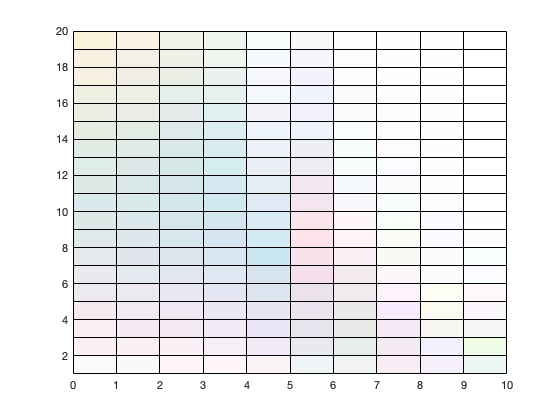

colors_I  = [213,242,248; 188,227,238; 161,216,234; 139,205,227; 127,196,222; 114,188,219; 104,179,213; 94,171,208; 88,164,201; 82,157,202; 74,149,194; 70,146,191; 65,138,184; 61,132,179; 56,127,177; 53,122,173; 48,117,168; 47,111,163; 44,108,160; 43,104,157] ./ 255;
colors_IA = [211,240,248; 183,224,235; 159,209,231; 139,199,224; 121,189,216; 110,180,211; 98,169,202;  90,162,199; 82,154,192; 76,148,186; 69,137,181; 64,131,174; 60,127,169; 58,121,163; 50,115,160; 47,109,154; 45,103,150; 43,99,147;  38,95,140;  36,91,137] ./ 255;
colors_IB = [214,236,244; 180,221,233; 155,206,225; 133,193,217; 117,183,210; 105,172,201; 93,162,192;  86,154,187; 76,145,178; 69,138,173; 63,128,167; 58,121,160; 54,115,155; 50,110,151; 46,103,145; 44,102,141; 40,94,132;  38,90,128;  37,86,125;  33,79,119] ./ 255;
colors_II = [204,231,237; 170,209,222; 140,191,208; 119,174,195; 102,158,182; 87,146,171;  76,133,162;  67,121,151; 57,111,138; 51,104,131; 44,94,122;  42,88,115;  40,80,109;  35,73,103;  32,69,95;   29,63,87;   24,57,80;   20,56,76;   19,50,70;   14,45,70] ./ 255;
colors_III= [197,219,222; 153,188,198; 121,164,176; 94,142,152;  78,122,134;  62,107,118;  54,93,106;   44,84,94;   37,74,86;   32,62,74;   28,57,63;   20,47,55;   19,42,51;   16,39,49;   12,32,39;   11,29,36;   10,24,31;   9,22,30;    7,19,27;    7,16,23] ./ 255;
colors_1C = [196,219,216; 152,186,184; 120,160,157; 97,140,137;  76,120,116;  65,101,99;   53,90,84;    46,78,73;   38,68,60;   33,58,52;   26,50,45;   24,47,40;   18,41,33;   17,37,33;   12,28,29;   14,27,26;   12,21,23;   11,19,21;   7,18,18;    6,16,16] ./ 255;
colors_3C = [186,202,193; 134,162,147; 102,130,113; 74,103,88;   58,83,69;    42,65,52;    34,54,43;    28,45,35;   20,36,25;   17,28,20;   15,23,17;   11,19,12;   9,15,9;     6,12,8;     5,10,8;     4,8,7;      0,6,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;
colors_5C = [173,175,163; 115,124,106; 76,87,67;    51,60,46;    37,45,30;    24,32,21;    16,22,16;    10,15,9;    9,11,7;     6,8,2;      4,6,2;      3,5,0;      2,4,2;      2,2,2;      2,2,2;      1,1,1;      0,0,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;
colors_7C = [153,149,123; 91,89,60;    56,53,33;    34,32,16;    21,19,9;     14,10,3;     7,7,3;       4,5,0;      4,5,0;      2,2,0;      1,1,1;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;
colors_9C = [129,114,78;  68,52,25;    35,26,11;    18,12,4;     9,7,2;       7,3,0;       5,0,0;       3,0,1;      1,1,1;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;

colors = [colors_I; colors_IA; colors_IB; colors_II; colors_III; colors_1C; colors_3C; colors_5C; colors_7C; colors_9C];

colorDiff = abs(colors - sRGB_color_type);
oneS = ones(200,3);
map = oneS - colorDiff;

colormapY = 1:z_max;
colormapX = 0:10;
% C_unit = (1:z_max)';
% C = repmat(C_unit, 1, 11)
C = [0*z_max+1:1*z_max; 1*z_max+1:2*z_max; 2*z_max+1:3*z_max; 3*z_max+1:4*z_max; 4*z_max+1:5*z_max; 5*z_max+1:6*z_max; 6*z_max+1:7*z_max; 7*z_max+1:8*z_max; 8*z_max+1:9*z_max; 9*z_max+1:10*z_max; 9*z_max+1:10*z_max]'

pcolor(colormapX, colormapY, C)
colormap(map)
